addpath(genpath('..'));


data = load('3dFab_1_deleted_points-SALSA.mat');
data_points1 =  data.data_points;

Filter non tissue points

3tissue = data_point.empty;
for i=1:length(data_points1)
    dp = copy(data_points1(i));
    if dp.tissue_flag == 1
        tissue = [tissue dp];
    end
end
data_points1 = tissue;
data_points2 = tissue;

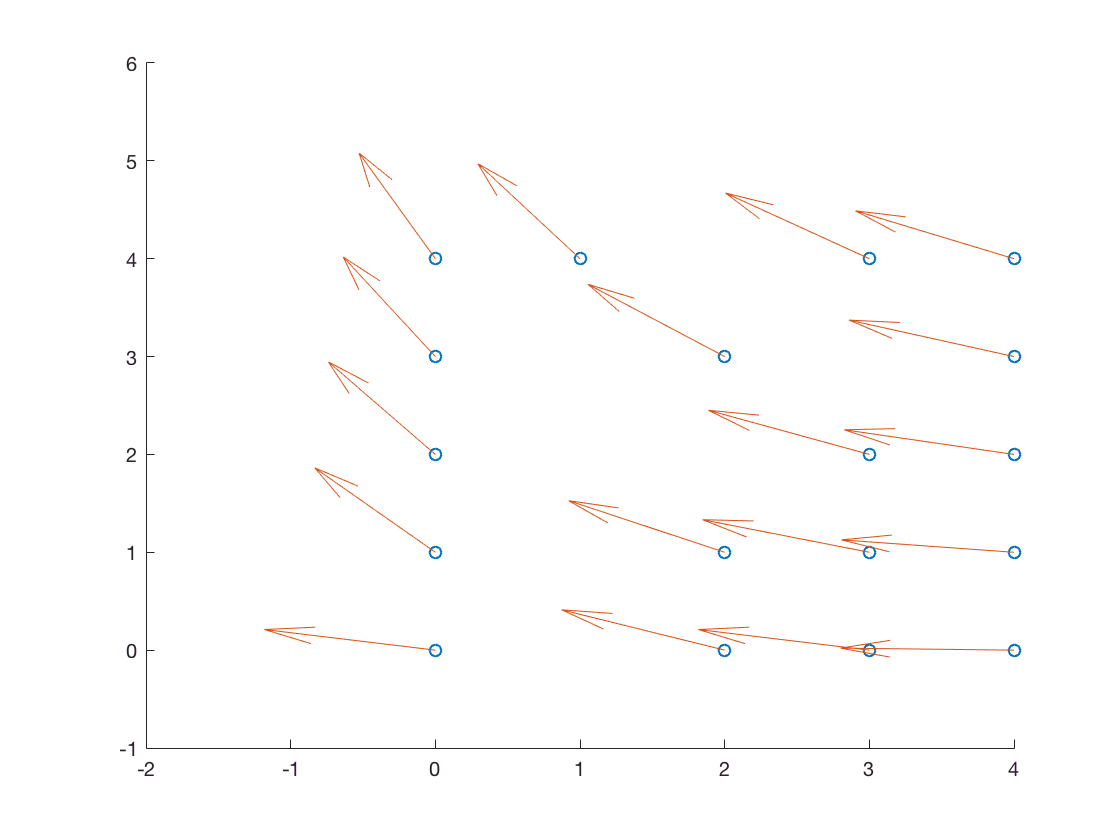

figure
hold on
scatter([data_points1(:).x],[data_points1(:).y])
u1=cos([data_points1(:).mean_odf]);
v1=sin([data_points1(:).mean_odf]);
quiver([data_points1(:).x],[data_points1(:).y], u1,v1)
hold off

theta = 90*pi/180;
T = [cos(theta) sin(theta) 0;
    -sin(theta) cos(theta) 0;
    0 0 1];


% [Ts, imageSize] = loadMatrices();
% T = translateMatrices(data_points1, Ts{1}, imageSize(1,:));

%Flip to fiji coordinates
for i = 1:length(data_points2)
    data_points2(i) = data_points1(i).ApplyTransformation(T);
    data_points2(i) = data_points2(i).ComputeStats();
end

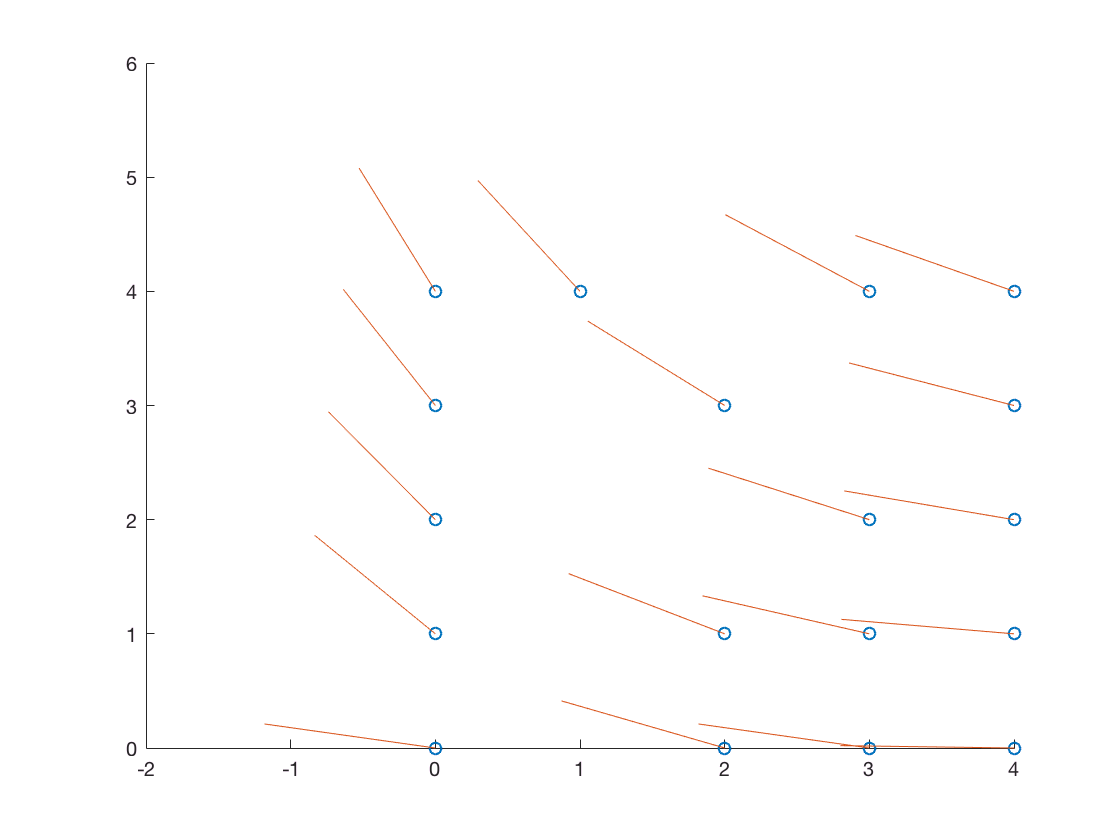

figure
hold on
scatter([data_points1(:).x],[data_points1(:).y])
u1=cos([data_points1(:).mean_odf]);
v1=sin([data_points1(:).mean_odf]);
quiver([data_points1(:).x],[data_points1(:).y], u1,v1,'.')
hold off

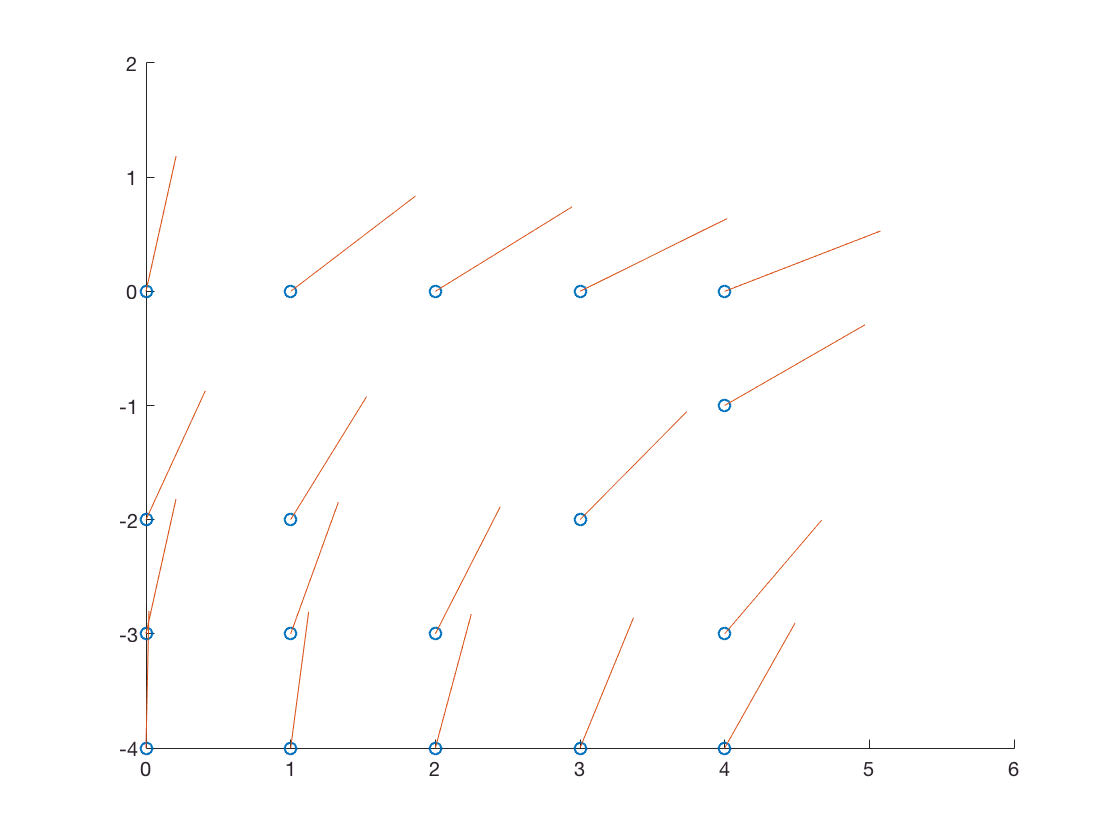


figure
hold on
scatter([data_points2(:).x],[data_points2(:).y])
u2=cos([data_points2(:).mean_odf]);
v2=sin([data_points2(:).mean_odf]);
quiver([data_points2(:).x],[data_points2(:).y], u2,v2,'.')
hold off